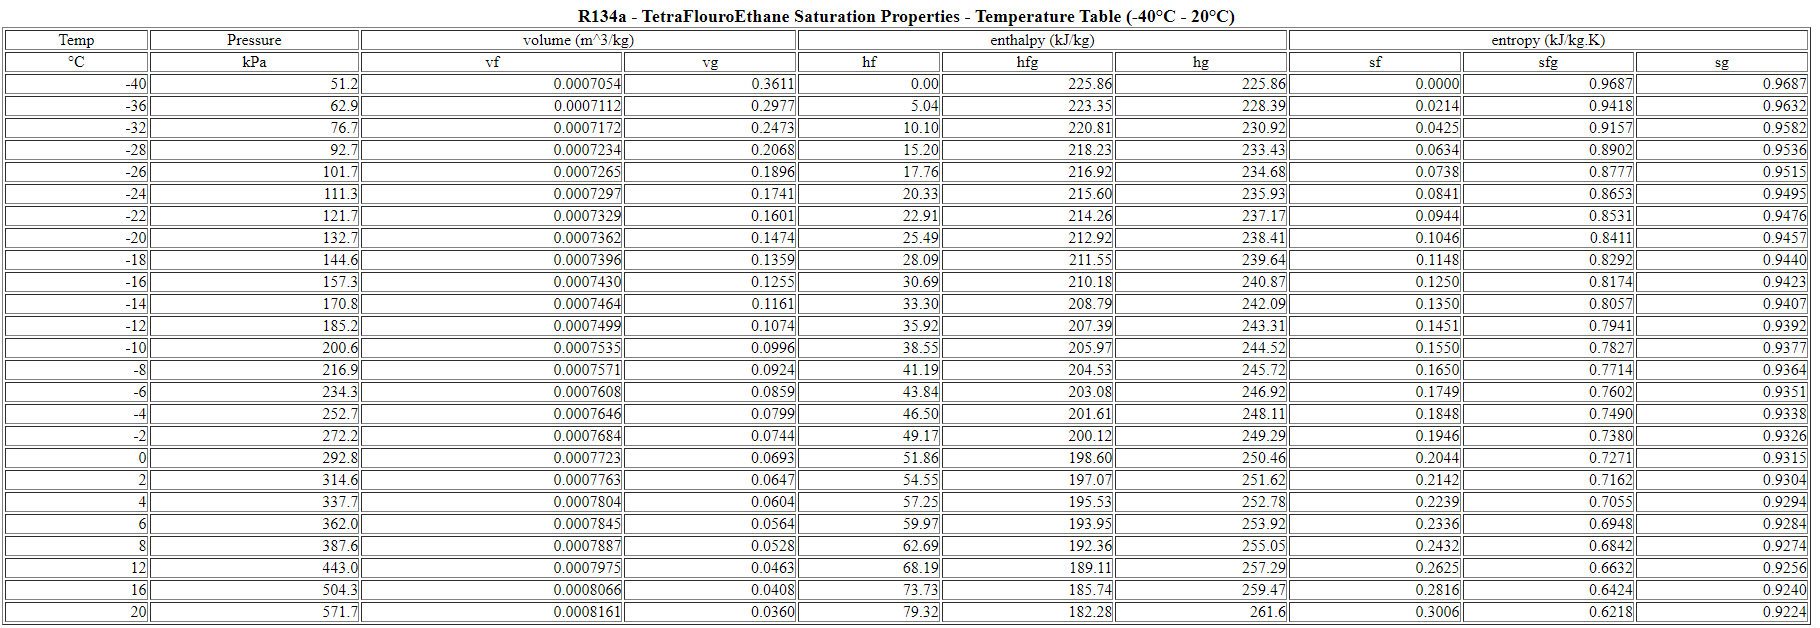

clc; clear all; format short

% r134a data - Nu antaget at være en ideal gas
R = 81.49 % Gaskonstant for r134a i J/(kg*K)

R = 81.4900

m = 1     % Antaget masse i liter

m = 1




% Stadie 1
% Indgang i kompressor
% Kølemiddelgassen r134a indsuges

p0 = 1    % Tryk før kompression

p0 = 1

t1 = 1    % Temperatur før kompression

t1 = 1

v1 = 1    % Volumeen før kompression

v1 = 1

h1 = 1    % Specifik entalpi før kompression

h1 = 1


% Stadie 2
% Kølemiddelgassen komprimes, antages for nu til at være adiabatisk -> 
% q12 = 0, altså ingen varme tilførsel til omgivelserne, men ikke tabsfrit
% w_diss > 0

p1 = 1    % Tryk efter kompression

p1 = 1

t2 = 1    % Temperatur efter kompression

t2 = 1

v2 = 1    % volumen efter kompression

v2 = 1

h2 = 1    % Specifik entalpi efter kompression

h2 = 1



% Trykændringsarbejde kompressoren laver
T = 1     % Konstant

T = 1


w12_p = m*R*T*log(p1/p0)

w12_p = 0


w12_v = m*R*T*log(v1/v2)

w12_v = 0

clc; clear all;

% Beholder volumen
slush = 1   % 1 liter

slush = 1

s_m3 = 0.001  % liter til m3

s_m3 = 1.0000e-03

r = 0.10/2    % radius på beholder

r = 0.0500

h_b = s_m3/(pi*r^2)

h_b = 0.1273


om_b = pi*r

om_b = 0.1571


% Rør størrelse
dy = 0.006

dy = 0.0060

di = 0.004

di = 0.0040


% Antal vindinger eller vendinger om beholderen
vind = h_b/dy           % Vi/endinger om rør

vind = 21.2207

ror_l = vind * om_b     % rørlængde i meter

ror_l = 3.3333


% indre rør volumen
v_i = di^2 * ror_l

v_i = 5.3333e-05


% Tryk fra coolpack ved -2 grader celsius
p = 2.72526*1e3

p = 2.7253e+03


m_i_ror = p*v_i

m_i_ror = 0.1453

ans = 2.7253e+03


% Entalpi for r134a
h1 = 220.4 * 1e3

h1 = 220400

h2 = 396.0 * 1e3

h2 = 396000



% Entalpi for slush
cV_slush = 3720       % J/(kg*K)

cV_slush = 3720

cV_r134 = 0.23901*1e3 % J/(kg*K)

cV_r134 = 239.0100

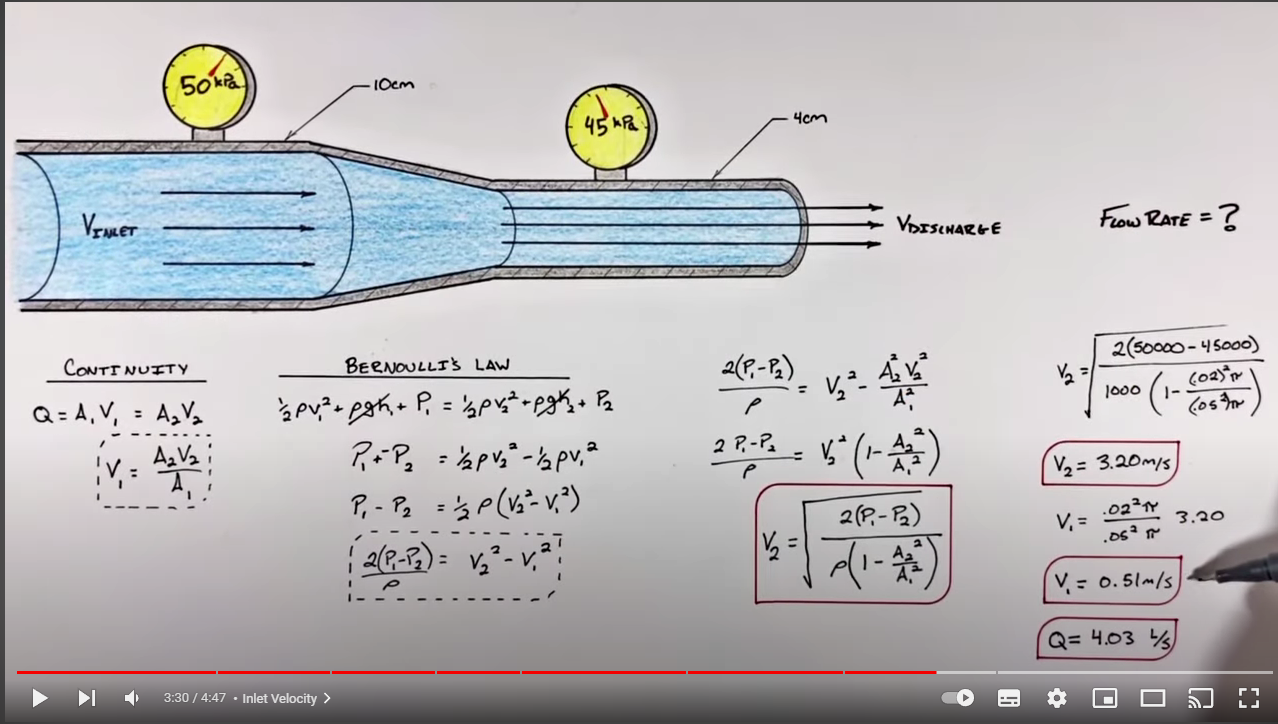

# Nye beregninger

clc; clear all;
u = symunit;

% Info for kompressor for datablad
Phi0 = 500 * u.W;
Vs = 16.15* u.cm^3;
n = 3000/u.min;

% Slagvolumenstrømmen
q_Vs = Vs*n;
q_Vs = vpa(unitConvert(q_Vs, u.m^3/u.h), 3)

$$q\_Vs = 2.91\,\frac{m^{3}}{h}$$



hs = [389.428 487.650 241.463 241.463] * u.kJ/u.kg;

vs = [0.150027, 0.025376] * u.m^3/u.kg; % volumenstrøm ved h1 og h2

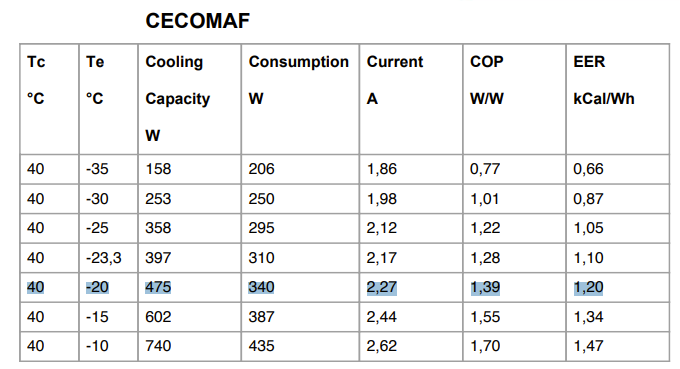

% Massestrøm
q_mr134a = Phi0/(hs(1) - hs(4));
q_mr134a = vpa(unitConvert(q_mr134a, "SI"), 3)

$$q\_mr134a = 0.00338\,\frac{\mathrm{kg}}{s}$$


% Indsugede volumenstrøm
q_v1 = q_mr134a * vs(1);
q_v1 = vpa(unitConvert(q_v1, "SI"),4)

$$q\_v1 = 0.000507\,\frac{m^{3}}{s}$$


% Volumenetrisk virkningsgrad
eta_v = q_v1/q_Vs;
vpa(unitConvert(eta_v, "SI"), 4)

$$ans = 0.6278$$


% Isentropisk effekt
Pis = q_mr134a*(hs(2) - hs(1));
Pis = vpa(unitConvert(Pis, u.kJ/u.kg), 3)

$$Pis = 0.332\,\frac{\mathrm{kJ}}{s}$$


% Isentropisk virkningsgrad
h_s2 = 429.04 * u.kJ/u.kg;
Pel = 266 * u.W; % Nominel cooling kapacity fra datablad
eta_s = Pis/Pel;

vpa(unitConvert(eta_s, "SI"), 3)

$$ans = 1.25$$


342/509

ans =          0.671905697445973




h1 = 390.4 * u.kJ/u.kg;

h2s = 430.8 * u.kJ/u.kg

$$h2s = \frac{2154}{5}\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$

h2r = 489.8 * u.kJ/u.kg

$$h2r = \frac{2449}{5}\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$


eta_c = vpa(unitConvert((h2s - h1)/(h2r - h1),"SI"),3)

$$eta\_c = 0.406$$

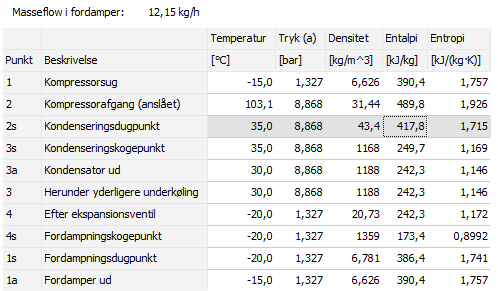

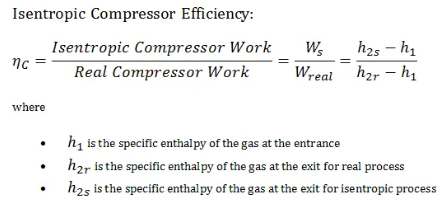

## Kondensator beregninger

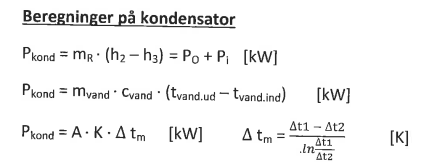

Pkond = q_mr134a * (hs(2) - hs(3))

$$Pkond = 0.83190957320618891600083605245499\,\frac{\mathrm{kJ}}{s}$$

Pkond = vpa(unitConvert(Pkond, u.W),15)

$$Pkond = 831.909573206189\,W$$


vpa( hs(3) - hs(2))

$$ans = -246.18700000000000613908923696727\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$

## Ventilberegninger

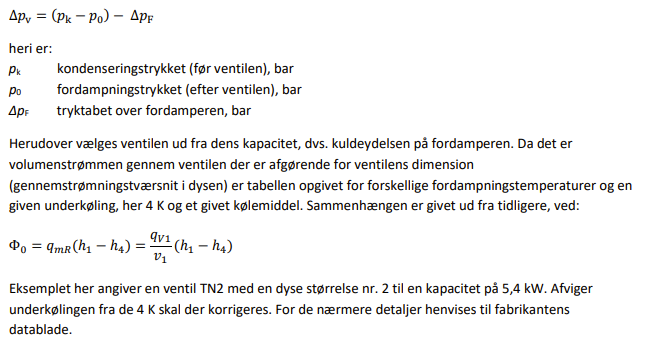

format longG

kelvin = 273.15;

pk = 8.868;
p0 = 1.327;
pf = 0;

pv = (pk - p0) - pf

pv =                      7.541



Tamb = 20;
T_Find = (kelvin + (-20)) * u.K;
T_Fud = (kelvin + (-15))*u.K;

R = 81.49 * u.J/(u.kg*u.K); % R134a gasconstant

p1 = 8.868 * u.bar;
p2 = 1.327 * u.bar;


v1 = R*T_Find/p1;
v2 = R*T_Find/p2;

v1 = vpa(unitConvert(v1,"SI"),3)

$$v1 = 0.0233\,\frac{m^{3}}{\mathrm{kg}}$$

v2 = vpa(unitConvert(v2,"SI"),3)

$$v2 = 0.155\,\frac{m^{3}}{\mathrm{kg}}$$

## Fordamper beregninger

q_mr134a * (hs(1) - hs(4))

$$ans = 0.49999999999778113788984062940625\,\frac{\mathrm{kJ}}{s}$$